Creación del FIS Mamdani

fis = mamfis("Name","Invernadero", ...
    "AndMethod","min", ...
    "OrMethod","max", ...
    "ImplicationMethod","min", ...
    "AggregationMethod","max", ...
    "DefuzzificationMethod","centroid");

Entradas

fis = addInput(fis,[-10 10],"Name","e");      % Error
fis = addInput(fis,[-10 10],"Name","de");     % Integral del Error

Función de Pertenencia de Entradas

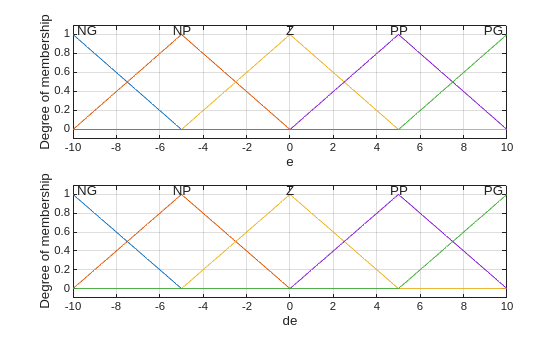

fis = addMF(fis,"e","trimf",[-10 -10 -5],"Name","NG");
fis = addMF(fis,"e","trimf",[-10 -5 0],"Name","NP");
fis = addMF(fis,"e","trimf",[-5 0 5],"Name","Z");
fis = addMF(fis,"e","trimf",[0 5 10],"Name","PP");
fis = addMF(fis,"e","trimf",[5 10 10],"Name","PG");

fis = addMF(fis,"de","trimf",[-10 -10 -5],"Name","NG");
fis = addMF(fis,"de","trimf",[-10 -5 0],"Name","NP");
fis = addMF(fis,"de","trimf",[-5 0 5],"Name","Z");
fis = addMF(fis,"de","trimf",[0 5 10],"Name","PP");
fis = addMF(fis,"de","trimf",[5 10 10],"Name","PG");

figure;
subplot(2,1,1)
plotmf(fis,"input",1);
grid on;
subplot(2,1,2)
plotmf(fis,"input",2);
grid on;

Funciones de Salida

fis = addOutput(fis,[-10 10],"Name","DeltaU");

fis = addMF(fis,"DeltaU","trimf",[-10 -10 -5],"Name","NG");
fis = addMF(fis,"DeltaU","trimf",[-10 -5 0],"Name","NP");
fis = addMF(fis,"DeltaU","trimf",[-5 0 5],"Name","Z");
fis = addMF(fis,"DeltaU","trimf",[0 5 10],"Name","PP");
fis = addMF(fis,"DeltaU","trimf",[5 10 10],"Name","PG");

Reglas

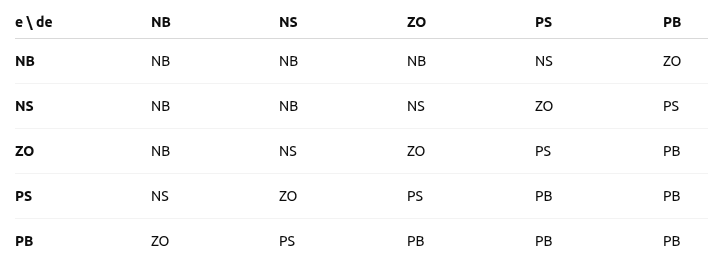

ruleList = [
              1 1  1  1 1;
              1 2  1  1 1;
              1 3  1  1 1;
              1 4  2  1 1;
              1 5  3  1 1;
              2 1  1  1 1;
              2 2  1  1 1;
              2 3  2  1 1;
              2 4  3  1 1;
              2 5  4  1 1;
              3 1  1  1 1;
              3 2  2  1 1;
              3 3  3  1 1;
              3 4  4  1 1;
              3 5  5  1 1;
              4 1  2  1 1;
              4 2  3  1 1;
              4 3  4  1 1;
              4 4  5  1 1;
              4 5  5  1 1;
              5 1  3  1 1;
              5 2  4  1 1;
              5 3  5  1 1;
              5 4  5  1 1;
              5 5  5  1 1
            ];

fis = addRule(fis,ruleList);

writeFIS(fis,"FIS_PI.fis");
K_e = 1;
K_de = 1;
K_du = 1;
